%{
ES115 Engineering Computer Applications
Module 6 Project: Profit vs Production

Author: Zulaikha Khan  
Instructor: Lynroy Grant  
Date: March 28, 2026  

Purpose:
This project models revenue, cost, and profit as functions of production
level. The goal is to analyze how profit changes as the number of units
produced increases, determine the production level that gives maximum
profit, and identify break-even points where profit is zero.

Inputs (Knowns):
- Production values (x) from 0 to 80 units
- Revenue model: R(x) = p·x, where p = 20 dollars per unit
- Cost model: C(x) = ax^2 + bx + c
    • a = 0.1 (quadratic cost factor)
    • b = 5 (linear cost)
    • c = 100 (fixed cost)

Outputs (Unknowns):
- Revenue, cost, and profit values
- Graph comparing revenue, cost, and profit
- Maximum profit and the production level where it occurs
- Break-even point(s) where profit is approximately zero

Engineering Workflow and Algorithms:
- Define production values over the given range
- Create revenue and cost functions using given parameters
- Compute profit as the difference between revenue and cost
- Plot all three functions on the same graph
- Use MATLAB functions to find maximum profit
- Identify approximate break-even points using logical conditions

MATLAB Tools / Functions Used:
- plot() for graphing multiple functions
- max() to find maximum profit
- find() to locate break-even points
- abs() for approximate zero comparison
- fprintf() and disp() for displaying results
- element-wise operations (.^) for calculations

Reflection After Completing the Project:
- I learned how revenue and cost functions interact to determine profit
  and how to visually analyze these relationships using graphs.
- I also understood how to find maximum values and approximate solutions
  like break-even points using MATLAB.
- If I were to improve this, I would solve for the exact break-even points
  algebraically instead of using an approximation.
- Difficulty Rating: 5/10 — the setup was straightforward, but interpreting
  the results and connecting them to real-world meaning took some thinking.
%}



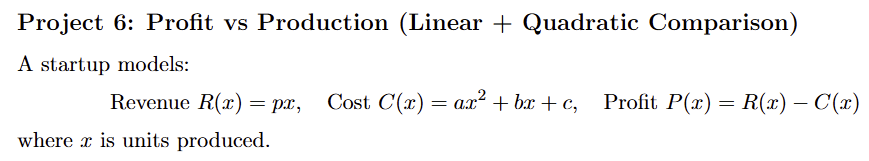

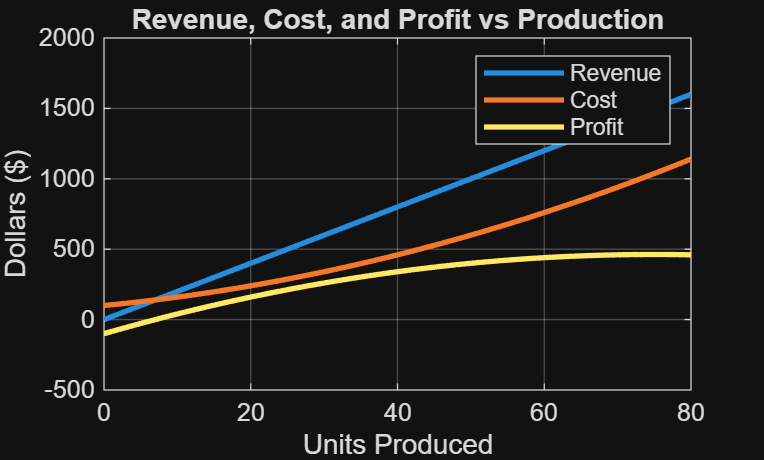


clear; clc; close all; 
 
% ---------------------------- 
% Define production values 
x = 0:1:80; 
 
% ---------------------------- 
% Choose realistic parameters 
p = 20; % revenue per unit 
a = 0.1; % quadratic cost factor 
b = 5; % linear cost 
c = 100; % fixed cost 
 
% ---------------------------- 
% Define functions 
R = p*x; % Revenue 
C = a*x.^2 + b*x + c; % Cost 
P = R - C; % Profit 
 
% ---------------------------- 
% Plot all three 
figure; 
plot(x, R, 'LineWidth', 2); hold on; 
plot(x, C, 'LineWidth', 2); 
plot(x, P, 'LineWidth', 2); 
 
title('Revenue, Cost, and Profit vs Production'); 
xlabel('Units Produced'); 
ylabel('Dollars ($)'); 
legend('Revenue', 'Cost', 'Profit'); 
grid on; 

 
% ---------------------------- 
% Find maximum profit 
[max_profit, idx] = max(P); 
x_max = x(idx); 
 
fprintf('Maximum profit of $%.2f occurs at x = %d units\n', max_profit, x_max); 

Maximum profit of $462.50 occurs at x = 75 units


 
% ---------------------------- 
% Find break-even points (P ≈ 0) 
index_be = find(abs(P) < 1); 
 
x_be = x(index_be); 
 
disp('Break-even point(s) (approximate x values):'); 

Break-even point(s) (approximate x values):


disp(x_be); 

     7

